% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]

% link dimension
lx=[1 1];
ly=[1 1];
lz=[1 1];

%material properties
density= 2660 ; % [kg/m3] AW 5083 alloy
rho=(density*1000)/100^3; %[g/cm3]

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];


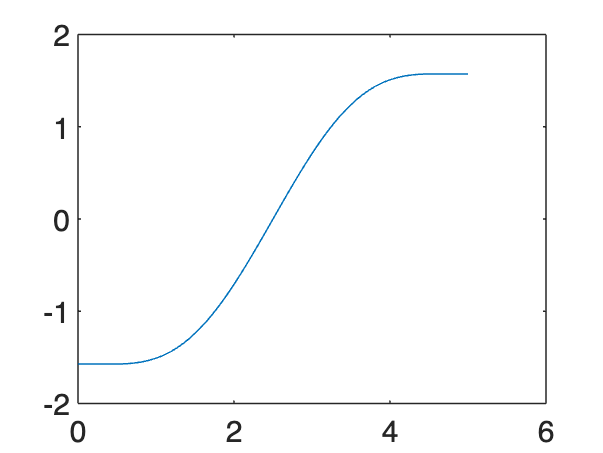

vand=@(t) [1 t t.^2 t.^3 t.^4 t.^5 t.^6 t.^7];
devand=@(t) [0 1 2*t 3*t^2 4*t^3 5*t^4 6*t^5 7*t^6];
dedevand=@(t) [0 0 2 6*t 12*t^2 20*t^3 30*t^4 42*t^5];

[A, vandermont] = criticaltrajectory(5, amax);

t = [0:0.01:5];
y = [];
for i=1:length(t)
    y=[y;A'*vand(t(i))'];
end
plot(t,y );

function [ Cx ,Cy ,Cz]= centerofmass(lx,ly,lz,rho)
 
    Cx= lx/rho;
    Cy= ly/rho;
    Cz= lz/rho;

end

function [J]=linkJacobian(i,q,lx,ly,lz,rho)

    [Cx, Cy, Cz]= centerofmass(lx(i),ly(i),lz(i),rho);
    J=zeros(6,2);
    J(1,1)= -Cy;
    J(2,1)= Cx;
    J(6,1)= 1;

    if(i==2)
        J(1,2)=lx(i)*sin(q(1))-Cy;
        J(2,2)=Cx-lx(i)*cos(q(1));
        J(6,2)=1;
    end

end

function [ inertia ] =linkinertia(i,lx,ly,lz,rho)

    [Cx, Cy, Cz]= centerofmass(lx(i),ly(i),lz(i),rho);
    %inertia = (lx(i)*ly(i)*lz(i)/12)*(ly(i)^2+lx(i)^2)*rho+...
        %lx(i)*ly(i)*lz(i)*rho*Cx;
    inertia = lx(i)*ly(i)*lz(i)*rho*((ly(i)^2+lx(i)^2)/12+Cx);

end

function [T, R, p] = dh(q,lx)

q12=q(1)+q(2);
c12=cos(q12);
s12=sin(q12);
T=[ c12, -s12, 0, lx(1)*cos(q(1))+lx(2)*c12 ;
    s12 c12 0 lx(1)*sin(q(1))+lx(2)*s12;
    0 0 1 0;
    0 0 0 1];

R=[c12, -s12, 0;
   s12 c12 0 ;
   0 0 1 ];
p =[lx(1)*cos(q(1))+lx(2)*c12 ; lx(1)*sin(q(1))+lx(2)*s12 ; 0];

end

function [ T ] = joint2op(q)
     
    q12=q(1)+q(2);
    c12=cos(q12);
    s12=sin(q12);

    T=[ 0 0 s12 ;
        0 1 0 ;
        1 0 c12];

end



function [ A, vandermont ]= criticaltrajectory(tf, amax, b)
if(nargin <3)
b=[ -pi/2; 0; 0; pi/2; 0; 0; 0; amax];
end

vand=@(t) [1 t t^2 t^3 t^4 t^5 t^6 t^7];

devand=@(t) [0 1 2*t 3*t^2 4*t^3 5*t^4 6*t^5 7*t^6];

dedevand=@(t) [0 0 2 6*t 12*t^2 20*t^3 30*t^4 42*t^5];

vandermont= [ vand(0);
                devand(0);
                dedevand(0);
                vand(tf);
                devand(tf);
                dedevand(tf);
                vand(tf/2);
                dedevand(tf/4)];

A=(vandermont^-1)*b;

end